%改变beamSize，不改变FL，探究beamSize和u，sigma的关系
%改变MLA pitch，进而改变其FN，探究FN和u，sigma的关系

clear;
close all;

## 添加路径

addpath('plane wave\')
addpath('镜头\')

## 参数设置

# Gaussian Beam

lambda=647e-6;
beamSize=flip(linspace(0.2,5,21));
beamStd=max(beamSize)/2.85;
noise=0.05;
beamAmp=1;


color=wavelength2color(lambda*10^6, 'gammaVal', 2.2, ...
    'maxIntensity', 1, 'colorSpace', 'rgb');
R=linspace(0,color(1),65535)';
G=linspace(0,color(2),65535)';
B=linspace(0,color(3),65535)';
mymap=[R G B];
colormap(mymap)



# MLA

rate=(0.15/41);%采样率（global）
rla1=-1.1;% 透镜1的曲率半径  
N=[27 41 51 71];%微透镜单元采样点数
BB=1:1:20;
%N=46;
d1 = N*rate;% 透镜单元边长
t = 1.2;% 透镜厚度
material={"F_SILICA"};

u=zeros(length(beamSize),length(N));
sigma=u;
FN=u;

num=beamStd./d1*5;            %数量
if num==0
    num=1;
end
area1 = mean(num.*d1);           % 光场的面积
area2=adapWin(rate,lambda,75);
area3=12.8;
area2=findClosestDivisible(area2,rate);
distance1 = 1;   % 投影距离
distance2 = 70;   % 投影距离
distance3 = 74.9;


# Diffuser

rpm=50000;%电机转速(圈每分钟)
rpus=rpm/60/1000/1000;
radius_diffuser=22;%散射片半径mm
velocity=2*pi*rpus*radius_diffuser;%线速度
deltat=1;%
T=100;%积分时间（μs）
times=floor(T/deltat);
route=velocity*T;
if route>2*pi*radius_diffuser
    route=2*pi*radius_diffuser;
    T=route/velocity;
    times=floor(T/deltat);
end
n=round(mean(N.*num));
diffuserAngle=0.5;   %散射片散射角度
diffuser=Diffuser(diffuserAngle,lambda);
szz=[round(route/rate)+n,n];
phase=Diffuser.generateDiffuser(diffuser,rate,szz);

# Fourier Lens

Dfl = area2;              %采样区域
file='OLD2440-T2M(JCOPTIX-F=74.9胶合).txt';
FL=readLens(file,lambda);

## 生成透镜相位

Lens.lensThickFcn(FL,Dfl,round(area2/rate));
Lens.lensSingle(FL);
Diffuser.diffuserSingle(diffuser)
distance2= single(distance2);
distance3= single(distance3);
area1= single(area1);
area2= single(area2);
area3= single(area3);

if canUseGPU
    Lens.lensGPUArray(FL)
    Diffuser.diffuserGPUArray(diffuser)
    distance2= gpuArray(distance2);
    distance3= gpuArray(distance3);
    area1= gpuArray(area1);
    area2= gpuArray(area2);
    area3= gpuArray(area3);
end
area=[area1,area1,area2,area3];
distance=[20,distance1,distance2,distance3];
fn=zeros(1,length(N));


for jj=1:length(d1)
    MLA1=Lens([rla1,inf],t,d1(jj),material,lambda);
    MLA2=Lens([inf,-rla1],t,d1(jj),material,lambda);
    Lens.lensArrayThickFcn(MLA1,N(jj),num(jj),'square');
    Lens.lensArrayThickFcn(MLA2,N(jj),num(jj),'square');
    Lens.lensSingle(MLA1)
    Lens.lensSingle(MLA2)
    if canUseGPU
        Lens.lensGPUArray(MLA1)
        Lens.lensGPUArray(MLA2)
    end
    lensgroup={MLA1,MLA2,FL};
    for kk=1:length(beamSize)

# Beam

        beamStd=beamSize(kk)/2.85;
        beam=GaussianBeam(beamAmp,beamStd,lambda);
        beams=GaussianBeam.defocused(beam,10,n,rate);
        I=zeros(round(area3/rate));

## 光场变换

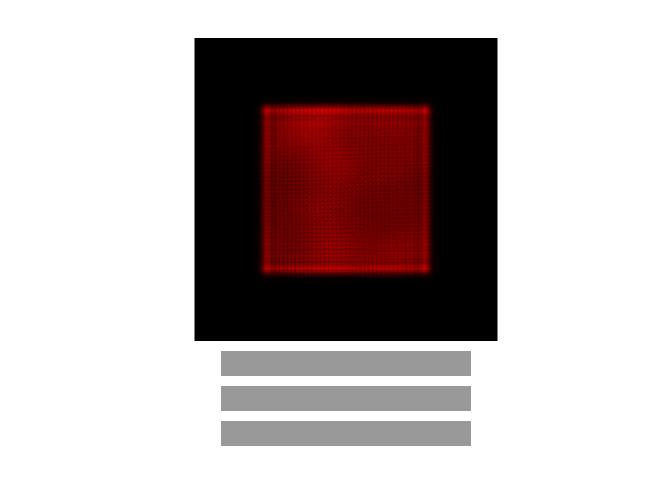

        
        for ii=1:times
            %叠加噪声
            beamss=GaussianBeam.beamNoise(beams,0.05,0);
            F = transform(beamss, area1, lambda, 20, [rate, rate]);
            index=round((velocity*(ii-1)*deltat)/rate+1);
            F=F.*phase(index:index+size(F,1)-1,:);
            F=ASMlensgroup(F,lensgroup,distance,area,lambda,rate);
        
            I_now=abs(F).^2;
            I = I+I_now;
            figure(1)
            Inorm=imnorm(I);
            figure(1)
            subplot(12,10,[1,90])
            imshow(uint16(Inorm*65536),mymap)
            subplot(12,10,[91,100])
            progressBar([100,1000],ii/times)
            drawnow
        end
        if kk==1
            threshold=otsuthresh(imhist(Inorm));
            im2=Inorm>threshold;
            
        end
        [u(kk,jj),sigma(kk,jj)]=homoanalyse3(Inorm,im2);   
        figure(2)

        figure(1)
        subplot(12,10,[101,110])
        progressBar([100,1000],kk/length(sigma));
    end
    fn(jj)=fresnelnum(MLA1,lambda);
    figure(1)
    subplot(12,10,[111,120])
    progressBar([100,1000],jj/length(N));
end

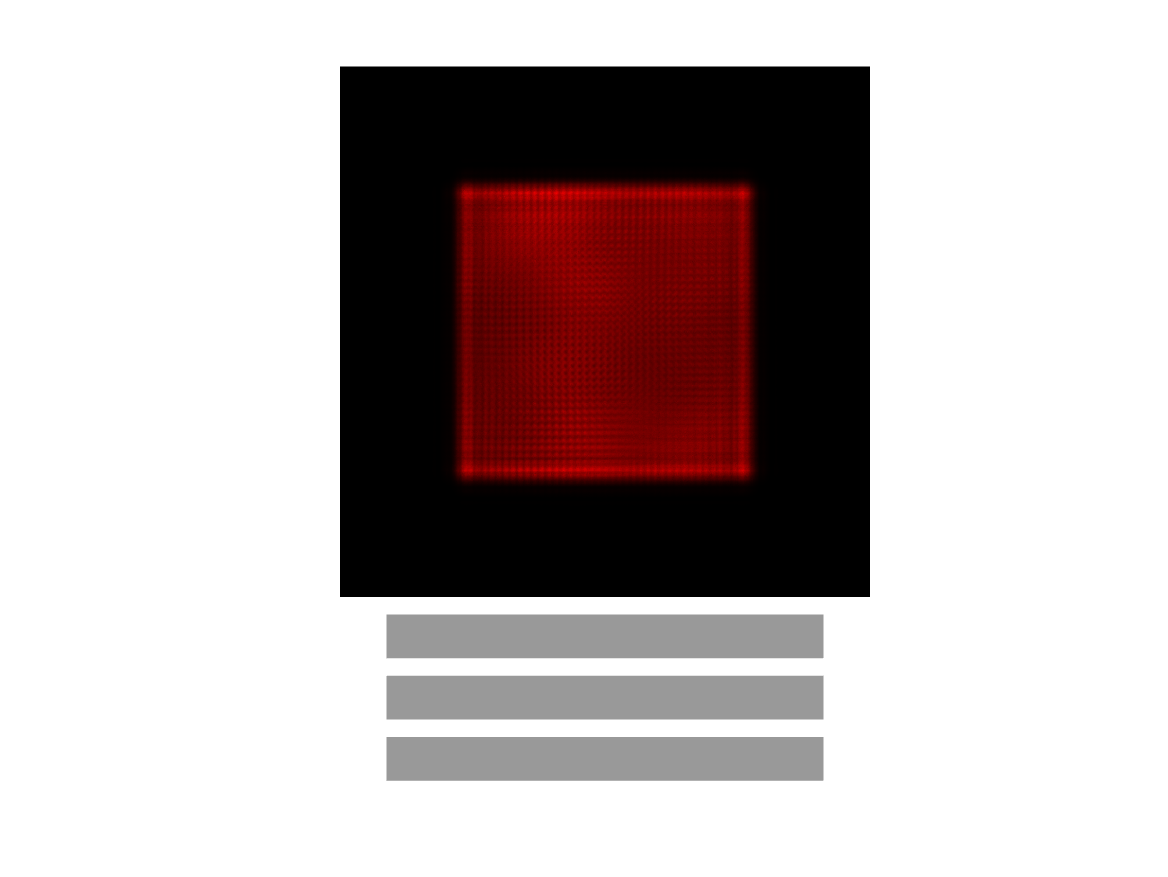

load('E:\File\Matlab\资料\color.mat');
colororder([color4;color3;color2;color1])

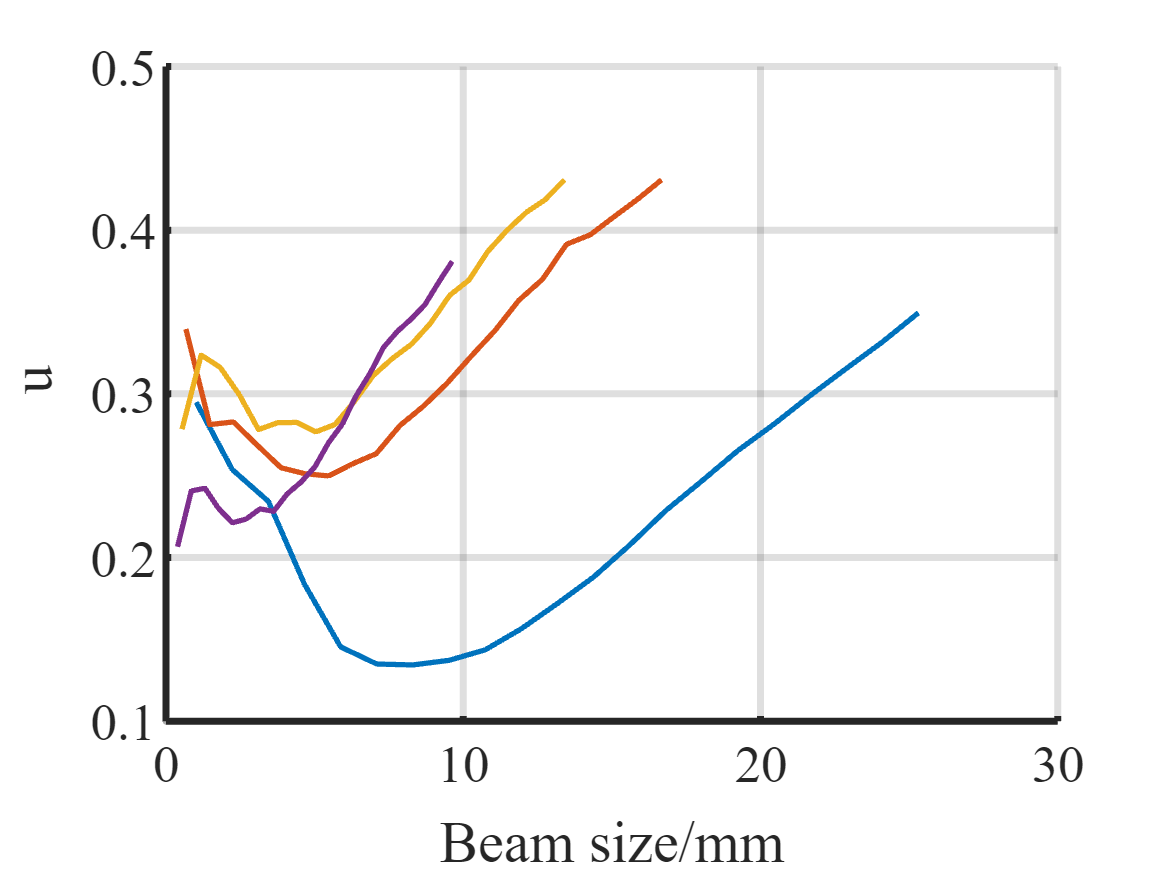

figure
hold on
B=zeros(length(d1),length(beamSize));
for ii=1:length(N)
B(ii,:)=beamSize/2/d1(ii);
plot(B(ii,:),u(:,ii),'linewidth',1.5)
end
xlabel('Beam size/mm')
ylabel('\it u')
grid on
set(gca,'Fontname','Times New Roman','FontSize',15,'linewidth',2)

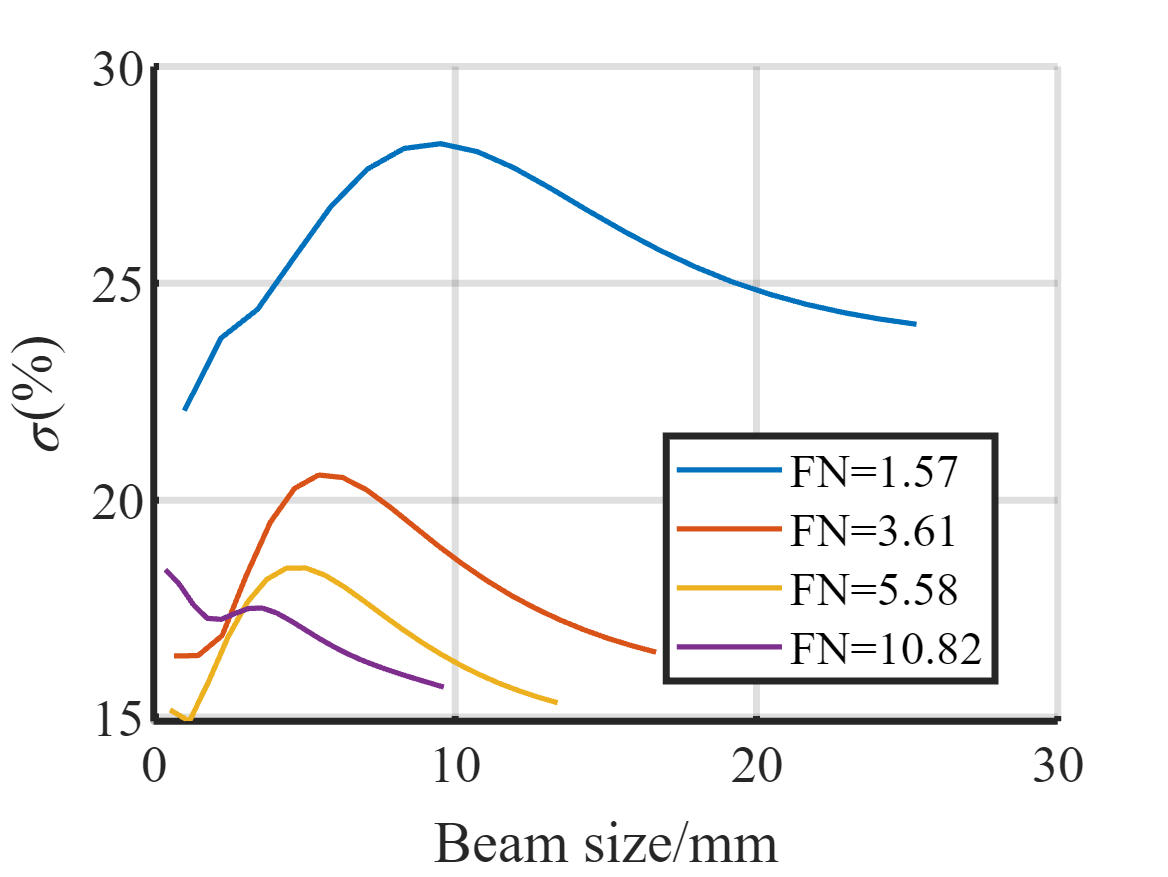

figure
hold on
for ii=1:length(N)
plot(B(ii,:),sigma(:,ii),'linewidth',1.5)
end
ylabel('\sigma(%)')
xlabel('Beam size/mm')
grid on

set(gca,'Fontname','Times New Roman','FontSize',15,'linewidth',2)
legend(['FN=' num2str(fn(1),'%.2f')],['FN=' num2str(fn(2),'%.2f')], ...
    ['FN=' num2str(fn(3),'%.2f')],['FN=' num2str(fn(4),'%.2f')], ...
    'location','best')